%Sample small linear system NN:
A = [2 -3 1
    -4 1 -2
    5 -3 9];
b = [1; 4; -2];
RootX = A\b

RootX =    -1.3692
   -1.2000
    0.1385



X = (10-(-10)).*rand(1000, 3) -10;
Y = X*A' - b'; 
%Y = Y + 1E-2 .*std(Y) .*randn(size(Y));
arraySize = [6, 4];

%Small INTEGER linear system NN:
%{
rng(16) %Random seed 3 for reproducability 
n = 4;
Ai = randi([-20, 20], n);     %(n rows, m col)
bi = randi([-20, 20], n, 1);  %(n rows)
rootXi = Ai\bi; %Size of rootX = A\b is of m rows.

X = (10-(-10)).*rand(1000, n) -10;
Y = X*Ai' - bi'; 
% Y = Y + 1E-2 .*std(Y) .*randn(size(Y));
arraySize = [16, 12, 6];
%}

%Small REAL NUMBER linear system NN:
%{
rng(32) %Random seed 3 for reproducability 
n = 4;
Ai = (20-(-20)).*rand(n)  -20;  %(n rows, m col)
bi = (20-(-20)).*rand(n,1)-20;  %(n rows)
rootXi = Ai\bi; %Size of rootX = A\b is of m rows.

X = (10-(-10)).*rand(1000, n) -10;
Y = X*Ai' - bi'; 
% Y = Y + 1E-2 .*std(Y) .*randn(size(Y));
arraySize = [6];
%}

rng("default") 
c = cvpartition(length(Y),"Holdout", 0.20);
trainingIdx = training(c); 
XTrain = X(trainingIdx,:);
YTrain = Y(trainingIdx,:);
testIdx = test(c);
XTest = X(testIdx,:);
YTest = Y(testIdx,:);
modelNN1 = fitrnet(XTrain,YTrain,"Standardize",true, ...
   "LayerSizes", arraySize)

modelNN1 =   RegressionNeuralNetwork
             ResponseName: {'y1'  'y2'  'y3'}
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 800
               LayerSizes: [6 4]
              Activations: 'relu'
    OutputLayerActivation: 'none'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [235×7 table]


  Properties, Methods



% modelNN1 = fitrnet(XTrain,YTrain, "LayerSizes", arraySize)
lossNN = loss(modelNN1, XTest, YTest)

lossNN = 7.8451e-07

%Quick test:
Yr = A*RootX - b;
Yt = predict(modelNN1, RootX')

Yt =    -1.9178   -1.7331    0.7918



% Yr = Ai*rootXi - bi;
% Yt = predict(modelNN1, rootXi')

StdRootX = (RootX - modelNN1.Mu') ./ modelNN1.Sigma'

Error using  - 
Arrays have incompatible sizes for this operation.

Related documentation

% StdRootX = (rootXi - modelNN1.Mu') ./ modelNN1.Sigma';

x0 = StdRootX;
z1 = modelNN1.LayerWeights{1}*x0 + modelNN1.LayerBiases{1};
z1max = max(0, z1);
z2 = modelNN1.LayerWeights{2}*z1max + modelNN1.LayerBiases{2};
z2max = max(0, z2);
z3 = modelNN1.LayerWeights{3}*z2max + modelNN1.LayerBiases{3};
fOUT = z3

filename = "FitRNet_Storage_RawData.xlsx"

filename = "FitRNet_Storage_RawData.xlsx"

% writematrix(X, filename,'Sheet', 1, 'Range', 'A1')
% writematrix(Y, filename,'Sheet', 2, 'Range', 'A1')

%There is n+1 parameter sets given n layers:
filename = "FitRNet_Storage_THETA.xlsx";
for i = 1:length(modelNN1.LayerSizes)+1
    writematrix(modelNN1.LayerWeights{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 

filename = "FitRNet_Storage_CCOEFF.xlsx";
for i = 1:length(modelNN1.LayerSizes)+1
    writematrix(modelNN1.LayerBiases{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 

filename = "FitRNet_Storage_THETA.xlsx";
for i = 1:length(modelNN1.LayerSizes)+1
    if i == 1
        A = modelNN1.LayerWeights{1} ./ modelNN1.Sigma
        writematrix(A, filename,'Sheet', i, 'Range', 'A1')
    else 
        writematrix(modelNN1.LayerWeights{i}, filename,'Sheet', i, 'Range', 'A1')
    end 
end %for 

A =     0.1588   -0.0536   -0.0812
    0.0564   -0.1593    0.0462
    0.3237   -0.2189    0.3708
   -0.5037    0.3407   -0.5771
    0.3544    0.2322   -0.0307
   -0.0083    0.1989    0.0339


filename = "FitRNet_Storage_CCOEFF.xlsx";
for i = 1:length(modelNN1.LayerSizes)+1
    if i == 1
        A = modelNN1.LayerBiases{1} - (modelNN1.LayerWeights{1} * (modelNN1.Mu ./ modelNN1.Sigma)');
        writematrix(A, filename,'Sheet', i, 'Range', 'A1');
    else 
        writematrix(modelNN1.LayerBiases{i}, filename,'Sheet', i, 'Range', 'A1')
    end 
end %for 


%%ODE NN WITH SINGLE INIT CONDITION
k1 = 5.7; k2 = 6.1;
c0 = [4.0; 1.0; 0.5; 0.0];
tspan = linspace(0, 2, 100); %constant time step

%Solve ODE:
dCdt = @(t, C) [
    -k1 * C(1)
     k2 * C(1) - k2 * C(2)
     k2 * C(2)
     k1 * C(1) + k2 * C(2)
];
[t, C] = ode45(dCdt, tspan, c0)

t =          0
    0.0202
    0.0404
    0.0606
    0.0808
    0.1010
    0.1212
    0.1414
    0.1616
    0.1818
    0.2020
    0.2222
    0.2424
    0.2626
    0.2828


C =     4.0000    1.0000    0.5000         0
    3.5649    1.3216    0.6440    0.5791
    3.1772    1.5584    0.8222    1.1450
    2.8316    1.7254    1.0250    1.6935
    2.5236    1.8350    1.2450    2.2214
    2.2491    1.8982    1.4756    2.7265
    2.0045    1.9243    1.7113    3.2069
    1.7864    1.9206    1.9484    3.6619
    1.5921    1.8932    2.1836    4.0915
    1.4190    1.8477    2.4145    4.4955
    1.2646    1.7887    2.6386    4.8740
    1.1270    1.7198    2.8547    5.2277
    1.0044    1.6438    3.0620    5.5576
    0.8952    1.5629    3.2597    5.8645
    0.7979    1.4795    3.4474    6.1495



%Train model to map Cn -> Cn+1;
X = C(1:end-1, :);
Y = C(2:end, :);

arraySize = [4];

rng("default") 
c = cvpartition(length(Y),"Holdout",0.20);
trainingIdx = training(c); 
XTrain = X(trainingIdx,:);
YTrain = Y(trainingIdx,:);
testIdx = test(c);
XTest = X(testIdx,:);
YTest = Y(testIdx,:);
modelNN2 = fitrnet(XTrain,YTrain,"Standardize",true, ...
    "LayerSizes", arraySize)

modelNN2 =   RegressionNeuralNetwork
             ResponseName: {'y1'  'y2'  'y3'  'y4'}
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 80
               LayerSizes: 4
              Activations: 'relu'
    OutputLayerActivation: 'none'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [199×7 table]


  Properties, Methods



lossNN2 = loss(modelNN2, XTest, YTest)

lossNN2 = 0.0044


%Predict values given same initial condition:
Cnew = zeros(100, 4);
Cnew(1,:) = c0;
for i = 2:100
    Cnew(i, :) = predict(modelNN2, Cnew(i-1, :))
end 

Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
         0         0         0         0
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
         0         0         0         0
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
         0         0         0         0


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew =     4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


Cnew = 100×4
    4.0000    1.0000    0.5000         0
    3.3850    1.7014    0.4568    0.5718
    3.0904    1.7191    0.7543    1.1639
    2.8121    1.7359    1.0354    1.7234
    2.5491    1.7517    1.3010    2.2519
    2.3007    1.7666    1.5520    2.7513
    2.0660    1.7807    1.7890    3.2231
    1.8442    1.7941    2.0130    3.6689
    1.6346    1.8067    2.2247    4.0900
    1.4367    1.8186    2.4246    4.4880
    1.2496    1.8298    2.6136    4.8639
    1.0729    1.8404    2.7921    5.2192
    0.9059    1.8505    2.9607    5.5548
    0.8083    1.7338    3.1819    5.8736
    0.7408    1.5929    3.3950    6.1542


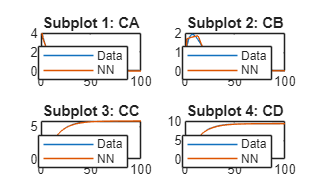

%Plot result:
p = tiledlayout(2,2);

nexttile;
plot([C(:,1), Cnew(:,1)])
legend('Data', 'NN')
title('Subplot 1: CA')

nexttile;
plot([C(:,2), Cnew(:,2)])
legend('Data', 'NN')
title('Subplot 2: CB')

nexttile;
plot([C(:,3), Cnew(:,3)])
legend('Data', 'NN')
title('Subplot 3: CC')

nexttile;
plot([C(:,4), Cnew(:,4)])
legend('Data', 'NN')
title('Subplot 4: CD')

clc
clear; 

%%ODE NN WITH DIFF INIT CONDITIONS
k1 = 5.7; k2 = 6.1; %Parameters
%Initial conditions:
c0 = [4.0  2.0  5.0  8.0  3.5
      1.0  0.4  1.0  5.0  1.0
      0.5  1.0  0.5  0.0  2.5
      0.1  0.0  2.0  0.0  0.5
];
sz1 = 1000;
tspan = linspace(0, 2, sz1); %constant time step

%Solve ODE for each set of initial conditions:
dCdt = @(t, C) [
    -k1 * C(1)              
     k2 * C(1) - k2 * C(2)  
     k2 * C(2)              
     k1 * C(1) + k2 * C(2)  
];

X = []; Y = [];
CComp = cell(1, 5);
for i = 1:5
    [t, C] = ode45(dCdt, tspan, c0(:,i))
    if i < 5
        X = [X;  C(1:end-1, :)]; 
        Y = [Y;  C(2:end, :)]; 
    end 
    CComp{i} = C;
end 

t =          0
    0.0020
    0.0040
    0.0060
    0.0080
    0.0100
    0.0120
    0.0140
    0.0160
    0.0180
    0.0200
    0.0220
    0.0240
    0.0260
    0.0280


C =     4.0000    1.0000    0.5000    0.1000
    3.9646    1.0461    0.5095    0.1549
    3.9295    1.0913    0.5195    0.2100
    3.8949    1.1355    0.5301    0.2653
    3.8607    1.1787    0.5413    0.3206
    3.8268    1.2210    0.5529    0.3762
    3.7933    1.2624    0.5651    0.4318
    3.7603    1.3029    0.5777    0.4876
    3.7275    1.3424    0.5909    0.5434
    3.6952    1.3811    0.6045    0.5994
    3.6632    1.4190    0.6186    0.6555
    3.6316    1.4560    0.6332    0.7117
    3.6004    1.4922    0.6482    0.7679
    3.5695    1.5275    0.6636    0.8243
    3.5389    1.5621    0.6795    0.8807


t =          0
    0.0020
    0.0040
    0.0060
    0.0080
    0.0100
    0.0120
    0.0140
    0.0160
    0.0180
    0.0200
    0.0220
    0.0240
    0.0260
    0.0280


C =     2.0000    0.4000    1.0000         0
    1.9873    0.4293    1.0021    0.0248
    1.9747    0.4581    1.0045    0.0498
    1.9622    0.4864    1.0072    0.0751
    1.9499    0.5141    1.0103    0.1005
    1.9377    0.5414    1.0138    0.1261
    1.9257    0.5683    1.0176    0.1519
    1.9138    0.5946    1.0217    0.1779
    1.9020    0.6205    1.0261    0.2041
    1.8904    0.6459    1.0308    0.2305
    1.8789    0.6709    1.0358    0.2570
    1.8675    0.6955    1.0412    0.2838
    1.8563    0.7196    1.0468    0.3106
    1.8452    0.7433    1.0528    0.3377
    1.8342    0.7665    1.0590    0.3649


t =          0
    0.0020
    0.0040
    0.0060
    0.0080
    0.0100
    0.0120
    0.0140
    0.0160
    0.0180
    0.0200
    0.0220
    0.0240
    0.0260
    0.0280


C =     5.0000    1.0000    0.5000    2.0000
    4.9532    1.0582    0.5096    2.0664
    4.9070    1.1152    0.5198    2.1329
    4.8612    1.1709    0.5308    2.1996
    4.8160    1.2253    0.5424    2.2664
    4.7713    1.2786    0.5547    2.3334
    4.7272    1.3307    0.5676    2.4005
    4.6835    1.3816    0.5812    2.4678
    4.6403    1.4313    0.5954    2.5352
    4.5976    1.4800    0.6101    2.6026
    4.5554    1.5275    0.6255    2.6702
    4.5136    1.5740    0.6414    2.7379
    4.4724    1.6194    0.6579    2.8057
    4.4316    1.6637    0.6750    2.8735
    4.3913    1.7070    0.6925    2.9414


t =          0
    0.0020
    0.0040
    0.0060
    0.0080
    0.0100
    0.0120
    0.0140
    0.0160
    0.0180
    0.0200
    0.0220
    0.0240
    0.0260
    0.0280


C =     8.0000    5.0000         0         0
    7.9192    5.0459    0.0583    0.1492
    7.8393    5.0902    0.1172    0.2980
    7.7603    5.1330    0.1767    0.4464
    7.6822    5.1744    0.2366    0.5944
    7.6050    5.2143    0.2970    0.7421
    7.5286    5.2528    0.3579    0.8894
    7.4532    5.2899    0.4193    1.0362
    7.3785    5.3257    0.4811    1.1827
    7.3048    5.3601    0.5434    1.3287
    7.2318    5.3932    0.6060    1.4743
    7.1597    5.4251    0.6691    1.6194
    7.0885    5.4556    0.7325    1.7642
    7.0180    5.4850    0.7963    1.9085
    6.9483    5.5131    0.8605    2.0523


t =          0
    0.0020
    0.0040
    0.0060
    0.0080
    0.0100
    0.0120
    0.0140
    0.0160
    0.0180
    0.0200
    0.0220
    0.0240
    0.0260
    0.0280


C =     3.5000    1.0000    2.5000    0.5000
    3.4702    1.0401    2.5095    0.5492
    3.4408    1.0794    2.5194    0.5986
    3.4117    1.1178    2.5298    0.6481
    3.3830    1.1554    2.5407    0.6978
    3.3545    1.1922    2.5520    0.7475
    3.3264    1.2283    2.5638    0.7974
    3.2986    1.2635    2.5760    0.8474
    3.2712    1.2980    2.5886    0.8976
    3.2440    1.3317    2.6017    0.9478
    3.2171    1.3647    2.6152    0.9981
    3.1906    1.3970    2.6290    1.0485
    3.1643    1.4286    2.6433    1.0990
    3.1384    1.4594    2.6579    1.1496
    3.1127    1.4896    2.6729    1.2003



%Train model to map Cn -> Cn+1;
arraySize = [6];

rng("default") 
c = cvpartition(length(Y),"Holdout",0.20);
trainingIdx = training(c); 
XTrain = X(trainingIdx,:);
YTrain = Y(trainingIdx,:);
testIdx = test(c);
XTest = X(testIdx,:);
YTest = Y(testIdx,:);
modelNN2 = fitrnet(XTrain,YTrain,"Standardize",true, ...
    "LayerSizes", arraySize)

modelNN2 =   RegressionNeuralNetwork
             ResponseName: {'y1'  'y2'  'y3'  'y4'}
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 3197
               LayerSizes: 6
              Activations: 'relu'
    OutputLayerActivation: 'none'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [247×7 table]


  Properties, Methods



lossNN2 = loss(modelNN2, XTest, YTest)

lossNN2 = 1.3707e-06


%Predict values given same initial condition:
Cnew = cell(1, 5); 
for j = 1:5
    Cnew{j} = zeros(sz1, 4);
    Cnew{j}(1,:) = c0(:, j);
    for i = 2:sz1
        Cnew{j}(i, :) = predict(modelNN2, Cnew{j}(i-1, :));
    end 
end 


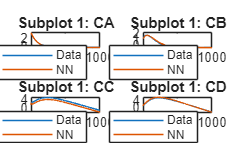

%Plot result: COMPARE Raw Data to NN:
m = 5;
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:4
    nexttile;
    plot([CComp{m}(:,i), Cnew{m}(:,i)])
    legend('Data', 'NN')
    title(ptitles(i, :))
end 

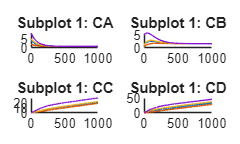

%Plot result: ALL Data given diff init cond.
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:4
    nexttile;
    hold on 
    for j = 1:4        
        plot(CComp{j}(:,i))
    end 
    title(ptitles(i,:))
    hold off
end 